# ROS Robot Motion Control

## Modeling and Control of Robotic Manipulators

Reminder: Follow the steps in the instruction files in the moodle course for using VM, ROS and Matlab

**Recommended Matlab Version: 2022b**

## Inverse Kinematics

#### 1.    Inverse Kinematics

Generate an inverse kinematics solver object `iksolver` for the rigid body tree object *ur*.

% %import robot ur10.urdf
% ur10 = importrobot('ur10.urdf');
% 
% %Generate a inverse kinematics solver object for the rigid body tree ur
% ikSolver = robotics.InverseKinematics('RigidBodyTree',ur10);

#### 2.    Define a target pose

Define a target pose in terms of a transform *tformTargetPose* that results from a translation $$[d_x \ d_y \ d_z]^T =[0.6 \ 0 \ 1.0]^T$$ and a rotation by Euler angles $$[\phi \ \theta \ \psi]^T=[\pi/4  \ \pi/4  \ -\pi/4]^T$$.

% targetPosition=[0.6 0 1.0];
% targetOrientation=[pi/4, pi/4, -pi/4];
% 
% %get tform of target pose
% tformTrans = trvec2tform(targetPosition);
% tformRot = eul2tform(targetOrientation);
% tformTargetPose = tformTrans * tformRot;

#### 3.    Determine the targetConf with the initialized ikSolver object above

Determine the inverse kinematics solution *targetConf* with the method `ik` for the target pose of the end effector link frame *'ee_link'* with a unit error weight vector $$w=[1 \ 1 \ 1 \ 1 \ 1 \ 1]$$. 

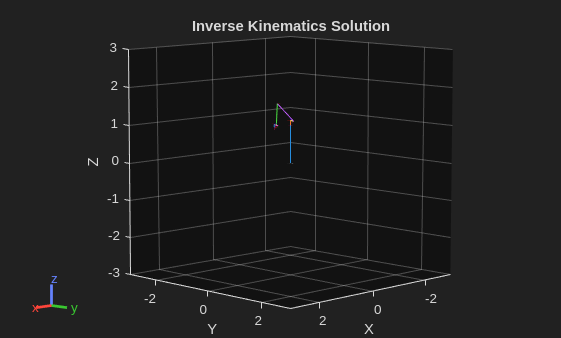

% weights = ones(6,1);
% initial_guess = JointVec2JointConf(ur10, [0 1 -2 2 1 1]);
% [targetConf, solnInfo] = ikSolver('ee_link', tformTargetPose, weights, initial_guess);


ur10 = importrobot('ur10.urdf');
%ur10.DataFormat = 'column';

ikSolver = robotics.InverseKinematics('RigidBodyTree',ur10);

targetPosition=[0.6 0 1];
targetOrientation=[pi/4, pi/4, -pi/4];

tformTrans=trvec2tform(targetPosition);
tformRot=eul2tform(targetOrientation);
tformTargetPose=tformTrans*tformRot;
weights = ones(6,1);

q_guess_vec = [-0.29, -0.30, 0.75, -2.25, 1.04, 4.37];
initial_guess = JointVec2JointConf(ur10,q_guess_vec);
[targetConf, solnInfo] = ikSolver('ee_link', tformTargetPose, weights, initial_guess);
show(ur10, targetConf);
title('Inverse Kinematics Solution');

## ROS2

#### 4.    Simulate the UR robot motion in Gazebo

To simulate the UR robot motion in Gazebo invoke the following launch files:

		`ros2 launch ur_simulation_gazebo ur_sim_control.launch.py ur_type:=ur10  gazebo_gui:=false`

The launch file starts Gazebo (hidden), RViz and the ROS controllers

#### 5.    Connect to ROS2

Create a ROS 2 node with ros2node

ros_node = ros2node("/matlab_node");

#### 6.    Show topics

Query the topics that are currently available on the network and obtain information about the topic *'/joint_states'* in particular the message type.

You notice that the *JointStatePublisher* publishes on the topic *'/joint_states'*

% List all available topics to see connections
ros2("topic", "list")

/clicked_point
/clock
/dynamic_joint_states
/goal_pose
/initialpose
/joint_state_broadcaster/transition_event
/joint_states
/joint_trajectory_controller/controller_state
/joint_trajectory_controller/follow_joint_trajectory/_action/feedback
/joint_trajectory_controller/follow_joint_trajectory/_action/status
/joint_trajectory_controller/joint_trajectory
/joint_trajectory_controller/state
/joint_trajectory_controller/transition_event
/parameter_events
/performance_metrics
/robot_description
/rosout
/tf
/tf_static



% Get specific info about joint_states to find the Message Type
%ros2("topic", "info", "joint_states")

#### 7.    Instantiate a subscriber for the topic above and receive messages

Instantiate a subscriber in Matlab for this topic and receive a message for the joint states.

Inspect the field *jointstate.Position* which denotes the vector of joint variables. The first six elements correspond to joints *shoulder_pan_joint*` to `*wrist_3_joint*`.`

jointStateSub = ros2subscriber(ros_node, "/joint_states", "sensor_msgs/JointState");

%(Extra) Receive one message to test if it works
firstMsg = receive(jointStateSub, 10);
disp(firstMsg)

    MessageType: 'sensor_msgs/JointState'
         header: [1×1 struct]
           name: {6×1 cell}
       position: [6×1 double]
       velocity: [6×1 double]
         effort: [6×1 double]



## Trajectory Control via Topic Interface

#### 8.    Information about ros message and helper function

Trajectory commands of message type *trajectory_msgs/JointTrajectory* are published on the topic  /joint_trajectory_controller/joint_trajectory*. *Instantiate a message object and inspect the message type structure

jointCommandMsg=ros2message('trajectory_msgs/JointTrajectory');

%(EXTRA) Display the message structure in Command Window
disp(jointCommandMsg)

    MessageType: 'trajectory_msgs/JointTrajectory'
         header: [1×1 struct]
    joint_names: {''}
         points: [1×1 struct]



The message type has the components h*eader*, j*oint_names* and p*oints*. j*oint_names* refer to the joint names in the URDF description of the robot. *Points* is an array of waypoints (*JointTrajectoryPoint*) that constitutes the sequence of poses plus time intervals the robot is supposed to track. Each *JointTrajectoryPoint* of message type *trajectory_msgs/TrajectoryPoint* has the components *Positions*, *Velocities* and *Accelerations* which correspond to joint state vector $$\mathbf{q}$$, joint velocity vector $$\dot{\mathbf{q}}$$ and joint acceleration vector $$\ddot{\mathbf{q}}$$. The component *TimeFromStart* specifies the time stamp of the waypoint, relative to the message time defined in the header of the *trajectory_msgs/JointTrajectory* message.

The helper function 	

		`function [ jointTrajectoryMsg ] = JointVec2JointTrajectoryMsg(robot, q, t, qvel, qacc)`

maps the  $$n \times m$$ arrays of joint vectors *q*,  joint velocities *qvel* and joint accelerations *qacc* and the $$n \times 1$$ vector of time stamps onto the corresponding joint trajectory message. The input argument *qvel* and *qacc* are optional and assume default zero values if omitted. 

#### 9.    Perform a point to point motion

Perform a point-to-point motion from the current configuration to the target configuration from task 3.

%create publisher
jointTrajectoryPub = ros2publisher(ros_node, "/joint_trajectory_controller/joint_trajectory", "trajectory_msgs/JointTrajectory");

%convert target configuration
q_target = JointConf2JointVec(targetConf);
t_target = 2.5;

% time offset to let robot finish motion
t_offset = 3; % increase if robot does not reach it's configuration in time

%send target configuration to the robot 
jointTrajectoryPub.send(JointVec2JointTrajectoryMsg(ur10, q_target, t_target));
pause(t_target + t_offset)

#### 10.    Execute the rated loop that monitors the temporal evaluation of the joint state vector

The motion command is executed in a fire and forget manner. Replace the `pause` command with a rated loop that monitors the temporal evolution of the joint state vector by subscribing to the */joint_states* topic. 

The helper function

`	function [ jointState, jointVel ] = JointStateMsg2JointState( robot, jointMsg )	`

converts a joint state message into joint state and joint velocity vectors.

% Move to start configuration
q_home = [0 0 0 0 0 0];
t_home = 2.5;
jointTrajectoryPub.send(JointVec2JointTrajectoryMsg(ur10, q_home, t_home));
pause(t_home + t_offset)

% Define target joint position and joint velocity
qvel=[0 0 0 0 0 0];

% Create rate object
rate = 50; % Hz
rateObj=robotics.Rate(rate);
tf = t_target + 0.5;
rateObj.reset; % reset time of rate object

% Preallocation
N = tf*rate;
timeStamp=zeros(N,1);
jointStateStamped=zeros(N,6); % array to record joint pose
jointVelStamped=zeros(N,6); % array to record joint velocity

% Store start time
jointStateMsg=jointStateSub.receive();
t0=double(jointStateMsg.header.stamp.sec)+ double(jointStateMsg.header.stamp.nanosec)*10^-9;

% Move and monitor
jointTrajectoryPub.send(JointVec2JointTrajectoryMsg(ur10, q_target, t_target));

for i=1:N
    % Receive and convert
    jointStateMsg=jointStateSub.receive();    
    [jointState, jointVel]=JointStateMsg2JointState(ur10,jointStateMsg);
    
    % Store signals
    jointStateStamped(i,:)=jointState;
    jointVelStamped(i,:)=jointVel;
    timeStamp(i)=double(jointStateMsg.header.stamp.sec)+ double(jointStateMsg.header.stamp.nanosec)*10^-9-t0;
    
    waitfor(rateObj);
end

#### 11.	Plot the joint state and joint velocity

Plot the joint state and joint velocity vector versus time as shown in figure 3. The joint motion profile is quintic to guarantee continuity of joint state, velocities and accelerations at way-points.

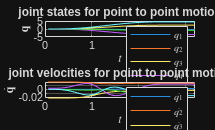

figure(1);
subplot(211);
xlim([0. 2.5])
plot(timeStamp, jointStateStamped);
xlabel('$t$','Interpreter','Latex');
ylabel('$\mathbf{q}$','Interpreter','Latex');
legend({'$q_1$','$q_2$','$q_3$','$q_4$','$q_5$','$q_6$'},'Interpreter','Latex');
title('joint states for point to point motion');
grid on

subplot(212);
xlim([0. 2.5])
plot(timeStamp, jointVelStamped);
xlabel('$t$','Interpreter','Latex');
ylabel('$\dot{\mathbf{q}}$','Interpreter','Latex');
legend({'$\dot{q_1}$','$\dot{q_2}$','$\dot{q_3}$','$\dot{q_4}$','$\dot{q_5}$','$\dot{q_6}$'},'Interpreter','Latex');
title('joint velocities for point to point motion');
grid on

#### 12.	Prepare a motion via two way-points

A general trajectory is composed of a sequence of way-points. The joint trajectory commands accept multiple joint configurations with time stamps to be traversed in that order. Command a trajectory  composed of the intermediate way-point $$\mathbf{q}_{target}$ and final way-point $$\mathbf{q}_2=[-1 \ 0 \ -1 \ 1 \ 0 \ 2]$$. 

% Back to home
jointTrajectoryPub.send(JointVec2JointTrajectoryMsg(ur10, q_home, t_home));
pause(t_home + t_offset)

% Create second waypoint
t_targets=[2.5; 6.0];
qf = [-1 0 -1 1 0 2];
q_targets=[q_target; qf];


task='12';    
task='14';    

switch task
    case '12'
        % stop at intermediate way-point % We set velocity to zero for both waypoints (2 points, 6 joints)
        qvel=zeros(2, 6); % stop at intermediate way-point
        
        
    case '14'   
        % stop at intermediate way-point
        qvel1 = [-0.4 0.0 0.0 -0.3 0.0 0.0];
        qvelf = [0 0 0 0 0 0];
        qvel = [qvel1; qvelf];
        
end

#### 13.	Perform motion via two way-points

Command, record and plot the joint motion through multiple way-points with the same code as for the point to point motion. Notice, that 

`	function [ jointTrajectoryMsg ] = JointVec2JointTrajectoryMsg(robot, q, t, qvel, qacc)`

accepts, a matrix of way-points *q* and a vector of time instances *t*. The motion is shown in figure 4. Notice, that the joint velocities at the intermediate way-point go to zero. This is desirable for joints $$q_2,q_5$$ which either stop or undergo a motion reversal at the first way-point. However, it seems awkward that joints $$q_1,q_4$$ come to a stop before continuing their movement.

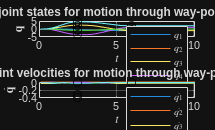

tf = t_targets(end) + 1.0;
rateObj.reset; % reset time of rate object

% Preallocation
N = tf*rate;
timeStamp=zeros(N,1);
jointStateStamped=zeros(N,6); % array to record joint pose
jointVelStamped=zeros(N,6); % array to record joint velocity

% Store start time
jointStateMsg=jointStateSub.receive();
t0=double(jointStateMsg.header.stamp.sec)+ double(jointStateMsg.header.stamp.nanosec)*10^-9;

% Move and monitor
jointTrajectoryPub.send(JointVec2JointTrajectoryMsg(ur10, q_targets, t_targets, qvel));

for i=1:N
    % Receive and convert
    jointStateMsg=jointStateSub.receive();    
    [jointState, jointVel]=JointStateMsg2JointState(ur10,jointStateMsg);
    
    % Store signals
    jointStateStamped(i,:)=jointState;
    jointVelStamped(i,:)=jointVel;
    timeStamp(i)=double(jointStateMsg.header.stamp.sec)+ double(jointStateMsg.header.stamp.nanosec)*10^-9-t0;
    
    waitfor(rateObj);
end

figure(2);
subplot(211);

plot(timeStamp',jointStateStamped);

hold on;
for i=1:size(q_targets,1)
    plot(t_targets(i),q_targets(i,:),'ko')
end
hold off;

xlabel('$t$','Interpreter','Latex');
ylabel('$\mathbf{q}$','Interpreter','Latex');
legend({'$q_1$','$q_2$','$q_3$','$q_4$','$q_5$','$q_6$'},'Interpreter','Latex');
title('joint states for motion through way-points');
grid on

subplot(212);

plot(timeStamp, jointVelStamped);

hold on;
for i=1:size(q_targets,1)
    plot(t_targets(i),qvel(i,:),'ko')
end
hold off;

xlabel('$t$','Interpreter','Latex');
ylabel('$\dot{\mathbf{q}}$','Interpreter','Latex');
legend({'$\dot{q_1}$','$\dot{q_2}$','$\dot{q_3}$','$\dot{q_4}$','$\dot{q_5}$','$\dot{q_6}$'},'Interpreter','Latex');
title('joint velocities for motion through way-points');
grid on

#### 14.	Modify the joint trajectory from task 12 and perform task 12 and 13

Modify the joint trajectory command by imposing a velocity vector $$\dot{\mathbf{q}}_1=[-0.4 \ 0.0 \ 0.0 \ -0.3 \ 0.0 \ 0.0]$$ for the first way-point. Notice, that for a smooth motion the joint velocities $$\dot{q}_1,\dot{q}_4$$ should assume their maximum at the first way-point. The maximum velocity equals is twice as large as the average velocity given by 


$$\mathbf{q}_{avg}=\frac{\mathbf{q}_f-\mathbf{q}_i}{t_f}$$


in which $$q_f$$ denotes the final joint state, $$q_i$$ the initial joint state and $$t_f$$ the total time of motion. The commanded velocity at the final way-point $$\dot{\mathbf{q}}_2$$ should still be zero for all joints as the motion is supposed to stop at the end of the trajectory. The motion with corrected way-point velocities is shown in figure 5.

## Trajectory Control via Action Server and Client

#### 15. Display the current list of actions on the ROS network

Display the current list of actions on the ROS network. Confirm that there is an action *'/*`joint_trajectory_controller/follow_joint_trajectory`*' *

% List all available actions to find the correct name
ros2("action", "list")

/joint_trajectory_controller/follow_joint_trajectory



% (Optional) Check info for the trajectory controller
% ros2("action", "info", "/joint_trajectory_controller/follow_joint_trajectory")

#### 16.	Instantiate an action client and an empty goal message

Instantiate an action client *followJointTrajectoryActClient*  for the action /joint_trajectory_controller/follow_joint_trajectory.

followJointTrajectoryTopicName="/joint_trajectory_controller/follow_joint_trajectory";
[followJointTrajectoryActClient]=ros2actionclient(ros_node, followJointTrajectoryTopicName, "control_msgs/FollowJointTrajectory");
followJointTrajectoryActClient.waitForServer("Timeout", 30);
followJointTrajectoryMsg=ros2message(followJointTrajectoryActClient);

#### 17.    Inspect the structure of the goal message

Inspect the structure of *followJointTrajectoryMsg*. The field *followJointTrajectoryMsg.Trajectory* corresponds to	the message type that you previously used for the topic interface. The message contains additional specification for path, goal and time tolerance, to monitor the accuracy of the commanded motion. 

disp(followJointTrajectoryMsg)

                 MessageType: 'control_msgs/FollowJointTrajectoryGoal'
                  trajectory: [1×1 struct]
        multi_dof_trajectory: [1×1 struct]
              path_tolerance: [1×1 struct]
    component_path_tolerance: [1×1 struct]
              goal_tolerance: [1×1 struct]
    component_goal_tolerance: [1×1 struct]
         goal_time_tolerance: [1×1 struct]



#### 18.    Inspect the helper function 

The helper function 

`	function [ followJointTrajectoryMsg ] = JointVec2FollowJointTrajectoryMsg(robot, q, t, qvel, qacc)`

accepts a matrix of way-points *q* (optional joint velocities *qvel* and accelerations *qacc*) and a vector of time instances *t*  as input parameters and generates the corresponding *followJointTrajectoryMsg*.

#### 19.	Follow a trajectory via the action client (non-blocking + monitoring)

Instead of waiting for the completion of the trajectory use `sendGoal` to continue. Replace the topic interface commands

`	jointTrajectoryPub.send(JointVec2JointTrajectoryMsg(ur10,q,t,qvel));`

with the equivalent action interface command

`	followJointTrajectoryMsg=JointVec2FollowJointTrajectoryMsg(ur10,q,t,qvel);`

`	followJointTrajectoryActClient.sendGoal(followJointTrajectoryMsg);`

Observe the command line output of the activation, feedback and result callback functions.	

% Back to home
jointTrajectoryPub.send(JointVec2JointTrajectoryMsg(ur10, q_home, t_home));
pause(t_home + t_offset)

% Preallocation
N = tf*rate;
timeStamp=zeros(N,1);
jointStateStamped=zeros(N,6); % array to record joint pose
jointVelStamped=zeros(N,6); % array to record joint velocity

% Store start time
jointStateMsg=jointStateSub.receive();
t0=double(jointStateMsg.header.stamp.sec)+ double(jointStateMsg.header.stamp.nanosec)*10^-9;

% Move and monitor
followJointTrajectoryMsg = JointVec2FollowJointTrajectoryMsg(ur10, q_targets, t_targets, qvel);
followJointTrajectoryActClient.sendGoal(followJointTrajectoryMsg);
for i=1:N
    % Receive and convert
    jointStateMsg=jointStateSub.receive();    
    [jointState, jointVel]=JointStateMsg2JointState(ur10,jointStateMsg);
    
    % Store signals
    jointStateStamped(i,:)=jointState;
    jointVelStamped(i,:)=jointVel;
    timeStamp(i)=double(jointStateMsg.header.stamp.sec)+ double(jointStateMsg.header.stamp.nanosec)*10^-9-t0;
    
    waitfor(rateObj);
end

#### 20.    Plot the joint states and joint velocities

Plot the joint states and joint velocities for the commanded sequence of way-points as shown in figure 5.

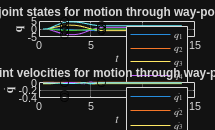

figure(4);
subplot(211);

plot(timeStamp, jointStateStamped);

hold on;
for i=1:size(q_targets,1)
    plot(t_targets(i),q_targets(i,:),'ko')
end
hold off;

xlabel('$t$','Interpreter','Latex');
ylabel('$\mathbf{q}$','Interpreter','Latex');
legend({'$q_1$','$q_2$','$q_3$','$q_4$','$q_5$','$q_6$'},'Interpreter','Latex');
title('joint states for motion through way-points');
grid on

subplot(212);

plot(timeStamp, jointVelStamped);

hold on;
for i=1:size(q_targets,1)
    plot(t_targets(i),qvel(i,:),'ko')
end
hold off;

xlabel('$t$','Interpreter','Latex');
ylabel('$\dot{\mathbf{q}}$','Interpreter','Latex');
legend({'$\dot{q_1}$','$\dot{q_2}$','$\dot{q_3}$','$\dot{q_4}$','$\dot{q_5}$','$\dot{q_6}$'},'Interpreter','Latex');
title('joint velocities for motion through way-points');
grid on